UNIVERSITY OF RWANDA, 

COLLEGE OF SCIENCE AND TECHNOLOGY, 

SCHOOL OF ENGINEERING, EEE DEPARTMENT

**Research Project: **

**Implementation of a Real-time Manuscript Scanner Software for Handwritten Lecturing Digitization.**

Group Members and Registration numbers:

- HABIYAREMYE NTWALI JANVIER: 218007332

- MALIZA CONSTANTINE: 218005312

- MBONIMPA PACOME SIMON: 218000124

# Report: Overview of Proposed Algorithms of Paper Movement Detection, Image Enhancement and Obstruction Removal.

## INTRODUCTION

In this report, we are going to provide an overview of proposed algorithms to deal with the basic parts of our implementation. Those parts include processes of Paper Movement Detection, Image Enhancement and Obstruction Removal. For each part (process), we will provide a flow chart indicating what the process should start with, how it will proceed and end. Explanations related to steps, together with sample images and codes are provided for illustration purposes only. The figure below indicates the main algorithm from which the processes we are going to discuss belong to.

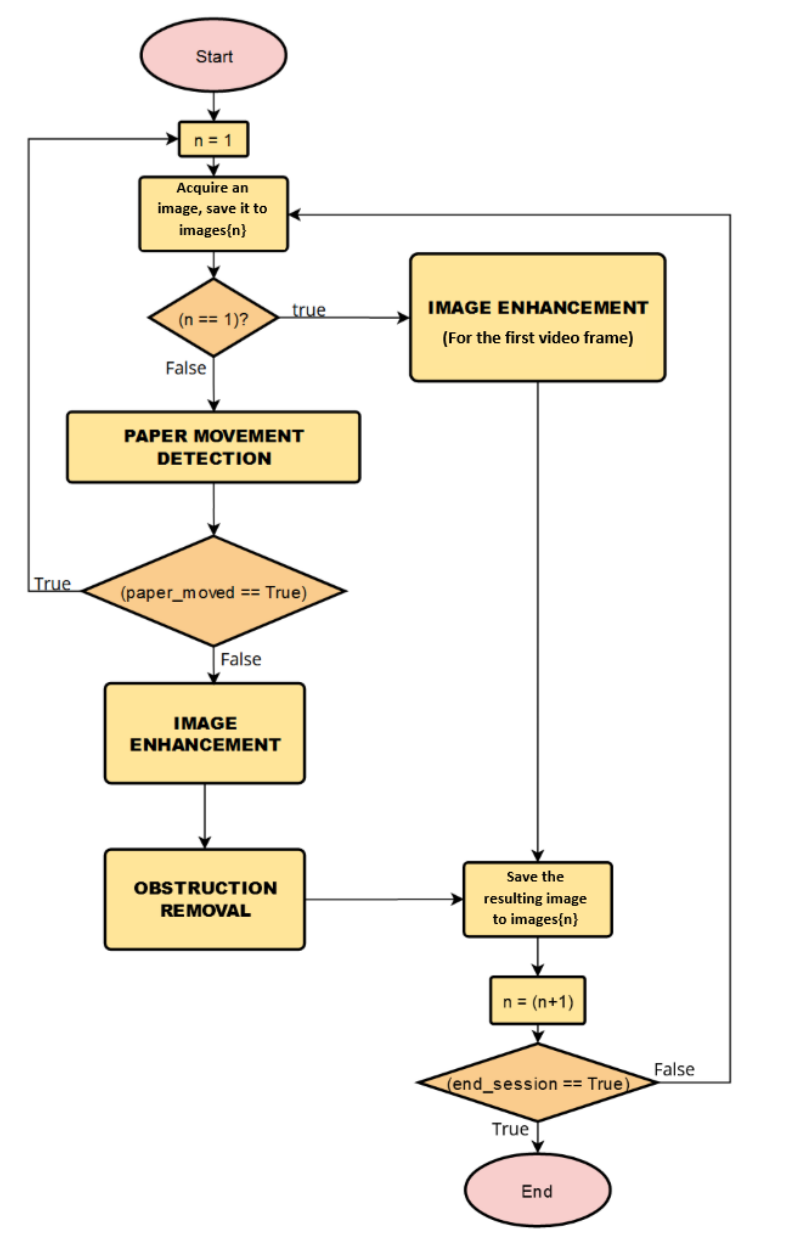

## I. Paper Movement Detection Using Correlation Coefficient.

To ensure that the obstruction can be removed, the system will need to first of all make sure that the paper has not been moved with respect to the camera's perspective. The following flowchart indicates where the Paper Movement Detection process belongs to in the main algorithm.

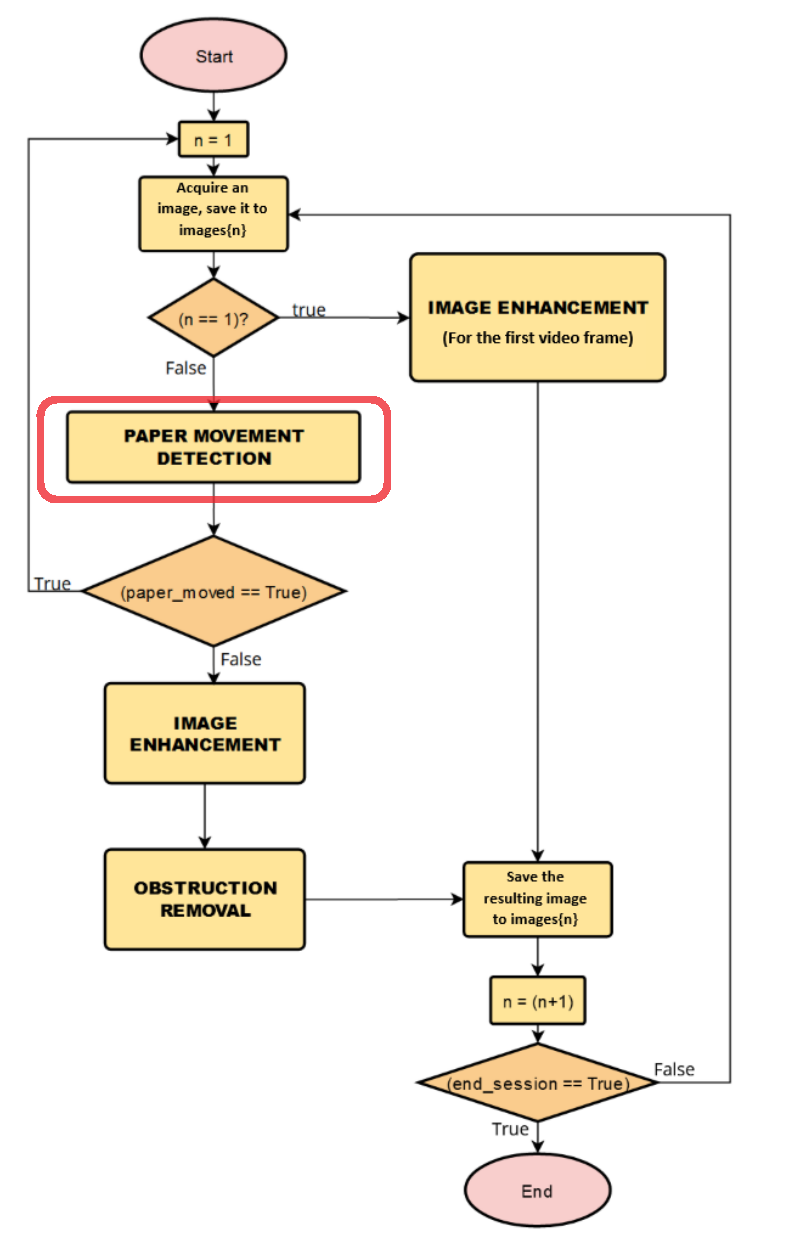

### METHODOLOGY ILLUSTRATION

In this section, we are going to illustrate the algorithm of paper movement detection. The flowchart below shows basic information on the paper movement detection algorithm. Note that the indicated numbers are the number of processes (steps) that are going to be explained.

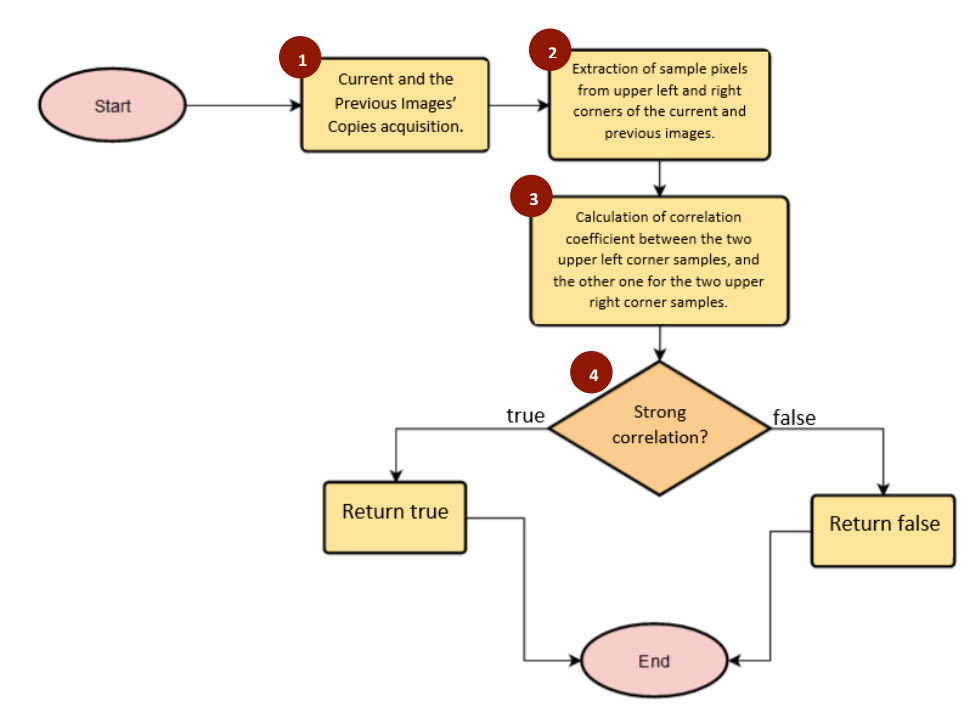

#### STEP 1: CURRENT AND PREVIOUS IMAGES (FRAMES) ACQUISITION

 In this demonstration, we will assume two images, where one represents a paper positioned well, and other represents the paper moved a bit from its initial position. 

Here at Step 1, This process will acquire a copy of the current image frame and the previous image frame.  It will also trim the images, so as to show the white paper section at maximum.

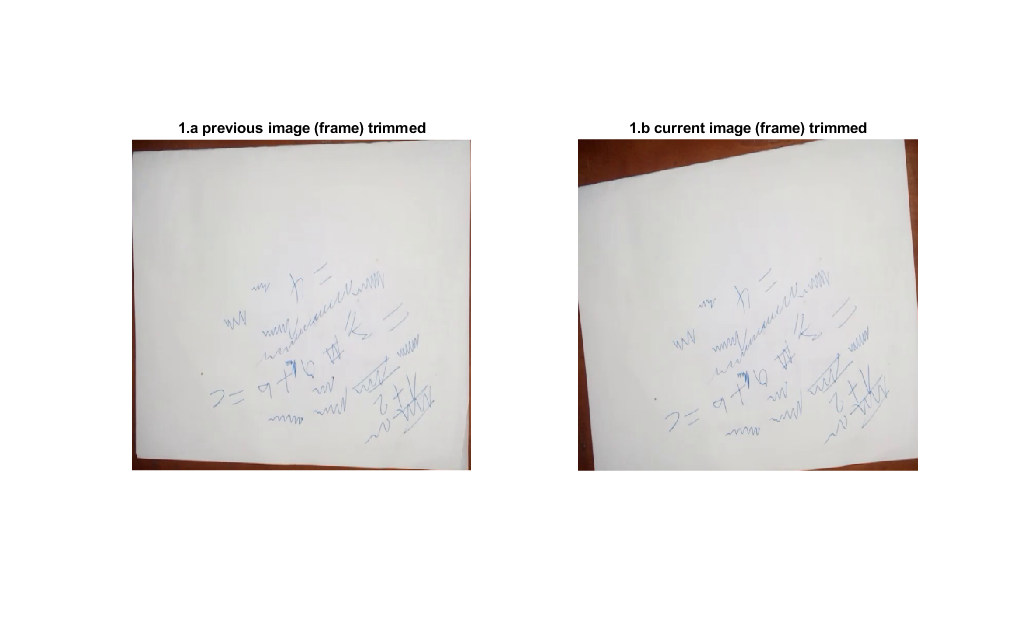

% global cropFactor; global cam;
cropFactor=0.1;

% rawImage1=snapshot(cam);
rawImage1= imread("outImageCr1.png");
[rawImage1 rowCr1 rowCr2 colCr1 colCr2]=whitePaperTrimmer(rawImage1,cropFactor);
subplot(1,2,1)
imshow(rawImage1)
title("1.a previous image (frame) trimmed")

% rawImage2=snapshot(cam);
rawImage2=imread("outImageCr2.png");
rawImage2 = rawImage2(rowCr1:rowCr2,colCr1:colCr2,:);
subplot(1,2,2)
imshow(rawImage2)
title("1.b current image (frame) trimmed")

#### STEP 2: SAMPLE PIXELS EXTRACTION FROM THE UPPER CORNERS OF THE TWO ACQUIRED IMAGES.

This process will take samples from the upper left and upper right corners of the two images. The acquired corner samples are shown in the figure below.

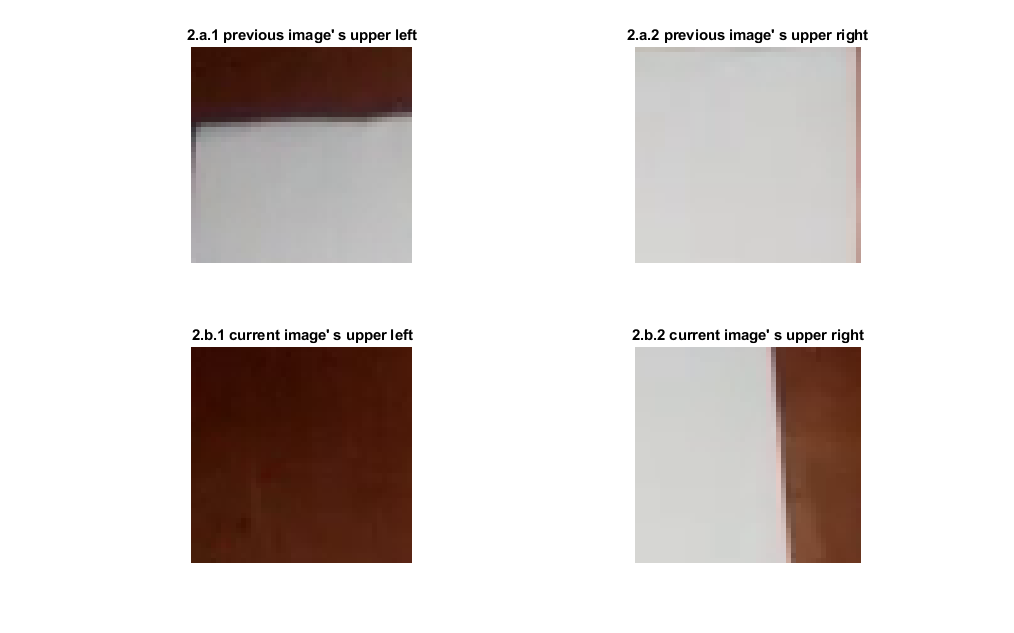

cropCornerArea=uint16(10); % area cropped from the corner, in percentage;
total_numberOfRows=rowCr2 - rowCr1 + 1;
total_numberOfColumns = colCr2 - colCr1 + 1;
farthest_row = total_numberOfRows * cropCornerArea / 100 ;
farthest_column = total_numberOfColumns * cropCornerArea / 100 ;
cropCorner1{1}=rawImage1(1:farthest_row,1:farthest_column,:);
cropCorner1{2}=rawImage1(1:farthest_row,end-farthest_column:end,:);
subplot(2,2,1)
imshow(cropCorner1{1})
title("2.a.1 previous image' s upper left")
subplot(2,2,2)
imshow(cropCorner1{2})
title("2.a.2 previous image' s upper right")

cropCorner2{1}=rawImage2(1:farthest_row,1:farthest_column,:);
cropCorner2{2}=rawImage2(1:farthest_row,end-farthest_column:end,:);
subplot(2,2,3)
imshow(cropCorner2{1})
title("2.b.1 current image' s upper left")
subplot(2,2,4)
imshow(cropCorner2{2})
title("2.b.2 current image' s upper right")

#### STEP 3: CORRELATION COEFFICIENTS CALCULATIONS BETWEEN THE EQUIVALENT CORNERS OF THE TWO ACQUIRED IMAGES.

To enhance the contrast, this process will first of all equalize the taken samples. Next, it will transform them into single column vectors, then compute two correlation coefficients: correlation coefficient between upper right corner of current image and the upper right corner of previous image, then correlation coefficient between upper left corner of current image and the upper left corner of previous image.

Corner1{1}=histeq(cropCorner1{1});
Corner1{2}=histeq(cropCorner1{2});
Corner2{1}=histeq(cropCorner2{1});
Corner2{2}=histeq(cropCorner2{2});

correlation_from_corner1=corr(double(Corner1{1}(:)),double(Corner2{1}(:)))

correlation_from_corner1 = 0.4252

correlation_from_corner2=corr(double(Corner1{2}(:)),double(Corner2{2}(:)))

correlation_from_corner2 = 0.6665

#### STEP 4: RETURNING A RESULT OF A TEST FOR A HIGH CORRELATION COEFFICIENT

For this process, the program has to decide whether or not the two correlation coefficients satisfies a minimum correlation coefficient. Normally, a correlation coefficient will range from 0 to 1, such that a value near to 1 indicates a high correlation. By experimentation, we found that in different conditions, 0.65 is the minimum coefficient of correlation that resulted when the paper was not moved. Therefore, this process will give a true answer if each of the two correlation coefficients satisfies the threshold condition of being greater than 0.65.

Decision_ = ((correlation_from_corner1 > 0.65) && (correlation_from_corner2 > 0.65))

Decision_ = logical
   0


### ALGORITHM IMPROVEMENT

Given that the calculation of coefficient of correlation takes too much time due to its high computational complexity **[****A. Mahmood and S. Khan, “Correlation-coefficient-based fast template matching through partial elimination,” *****IEEE Transactions on Image Processing*****, vol. 21, no. 4, pp. 2099–2108, Aug. 2010. ****]**, we developed a new approach so as to tackle with the challenge of time efficiency, as a real-time constraint. The new approach proposed had to start by thresholding the equalized pixel samples from the papers' upper corners. As various thresholding models rely on contrast enhancement (**[P. Kandhway and A. K. Bhandari, “An optimal adaptive thresholding based sub-histogram equalization for brightness preserving image contrast enhancement,” *****Multidimensional Systems and Signal Processing*****, vol. 30, no. 4, pp. 1859–1894, Feb. 2019. ]** and **[****S. N and V. S, “Image segmentation by using thresholding techniques for medical images,” *****Computer Science & Engineering: An International Journal*****, vol. 6, no. 1, pp. 1–13, Feb. 2016. ****]**), the image equalization will enhance the contrast significantly, so as to prepare the image for the thresholding. The process had then to compare the resulting thresholded binary patterns using the binary XOR operation. The resulting data would indicate which pixels have changed, and those that didn't change, if the paper had been moved. By experimentation, we found that the maximum percentage of pixels that changed when the paper was not moved was 30%. This was due to the presence of noise that varied in different cases.

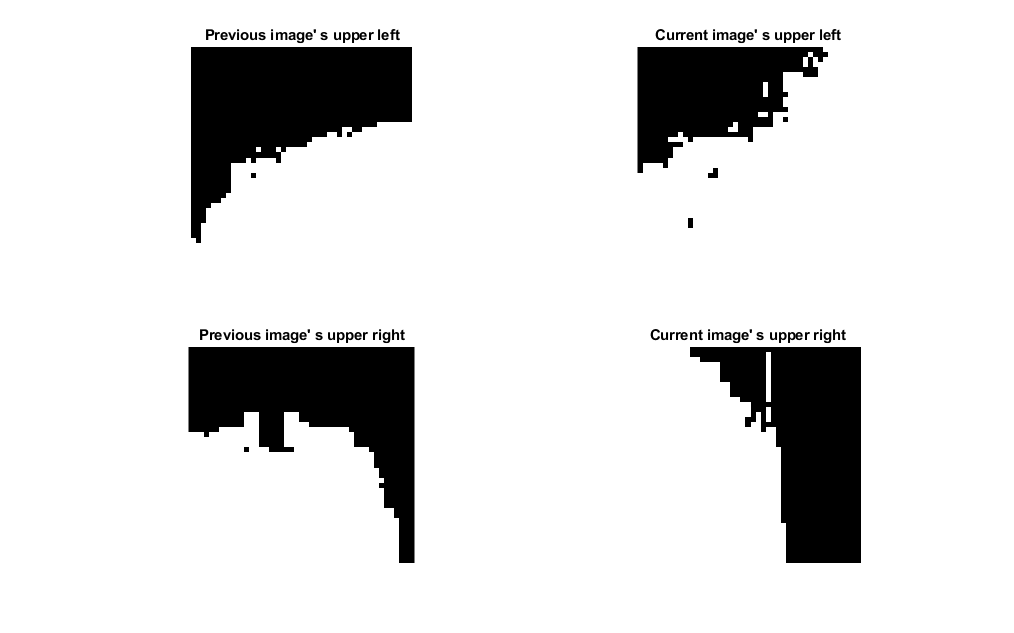

Corner1{1}= rgb2gray(Corner1{1});
Corner1{2}= rgb2gray(Corner1{2});
Corner2{1}= rgb2gray(Corner2{1});
Corner2{2}= rgb2gray(Corner2{2});

Corner1{1}=imbinarize(Corner1{1},0.5);
Corner1{2}=imbinarize(Corner1{2},0.5);
Corner2{1}=imbinarize(Corner2{1},0.5);
Corner2{2}=imbinarize(Corner2{2},0.5);

subplot(2,2,1)
imshow(Corner1{1})
title("Previous image' s upper left")
subplot(2,2,2)
imshow(Corner2{1})
title("Current image' s upper left")
subplot(2,2,3)
imshow(Corner1{2})
title("Previous image' s upper right")
subplot(2,2,4)
imshow(Corner2{2})
title("Current image' s upper right")

xor_from_corner1=xor((Corner1{1}(:)),(Corner2{1}(:)));
xor_from_corner2=xor((Corner1{2}(:)),(Corner2{2}(:)));

sum_xor_from_corner1=sum(xor_from_corner1(:));
sum_xor_from_corner2=sum(xor_from_corner2(:));

ratio_xor_from_corner1 = sum_xor_from_corner1/length(xor_from_corner1)

ratio_xor_from_corner1 = 0.1929

ratio_xor_from_corner2 = sum_xor_from_corner2/length(xor_from_corner2)

ratio_xor_from_corner2 = 0.3034

### COMPARISION OF TIME USAGE BETWEEN THE CORRELATION COEFFICIENT APPROACH AND THE XOR APPROACH.

In this section, we are going to compare the time usage of the two approaches: coefficient correlation approach against the XOR approach. We will generate different random images of 1 megapixels to 5 megapixels and graph the time it will take for the computer to execute each dataset using each of the two approaches. For each approach, the computer will execute the step number 3, assuming that the given image represents the corner samples of the current and the previous image frame.

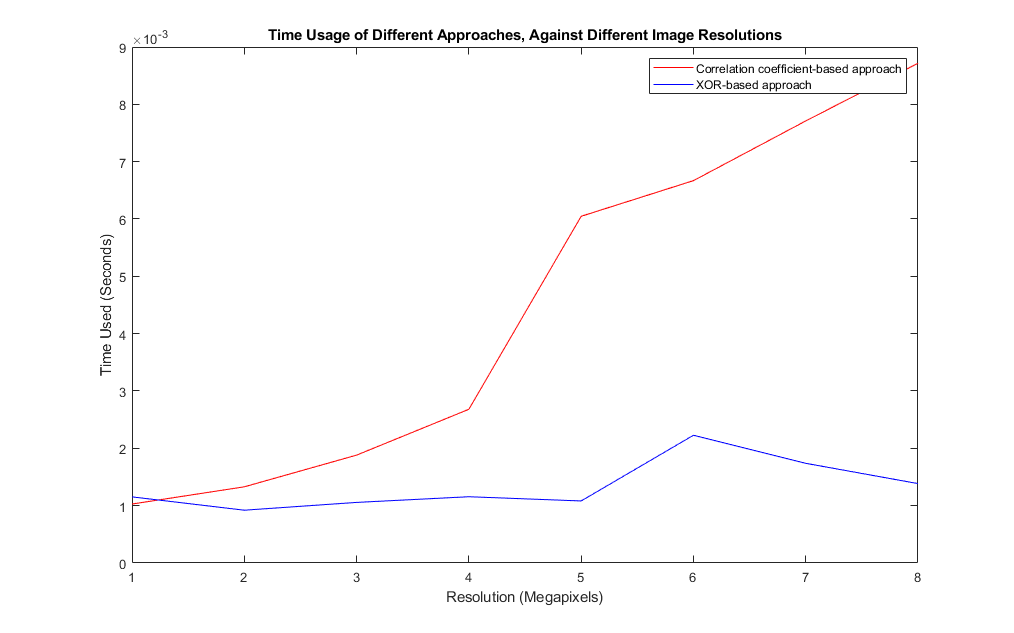

cstant = 100;
i100_pixels=uint8(255*rand(10*cstant,10,3));
i200_pixels=uint8(255*rand(20*cstant,10,3));
i300_pixels=uint8(255*rand(30*cstant,10,3));
i400_pixels=uint8(255*rand(40*cstant,10,3));
i500_pixels=uint8(255*rand(50*cstant,10,3));
i600_pixels=uint8(255*rand(60*cstant,10,3));
i700_pixels=uint8(255*rand(70*cstant,10,3));
i800_pixels=uint8(255*rand(80*cstant,10,3));

for q=1:1:8
    
    tic;
    corr_Approach(i100_pixels);
    t_correlation(1)=toc;
    tic;
    corr_Approach(i200_pixels);
    t_correlation(2)=toc;
    tic;
    corr_Approach(i300_pixels);
    t_correlation(3)=toc;
    tic;
    corr_Approach(i400_pixels);
    t_correlation(4)=toc;
    tic;
    corr_Approach(i500_pixels);
    t_correlation(5)=toc;
    tic;
    corr_Approach(i600_pixels);
    t_correlation(6)=toc;
    tic;
    corr_Approach(i700_pixels);
    t_correlation(7)=toc;
    tic;
    corr_Approach(i800_pixels);
    t_correlation(8)=toc;
    
    tic;
    xor_Approach(i100_pixels);
    t_xor(1)=toc;
    tic;
    xor_Approach(i200_pixels);
    t_xor(2)=toc;
    tic;
    xor_Approach(i300_pixels);
    t_xor(3)=toc;
    tic;
    xor_Approach(i400_pixels);
    t_xor(4)=toc;
    tic;
    xor_Approach(i500_pixels);
    t_xor(5)=toc;
    tic;
    xor_Approach(i600_pixels);
    t_xor(6)=toc;
    tic;
    xor_Approach(i700_pixels);
    t_xor(7)=toc;
    tic;
    xor_Approach(i800_pixels);
    t_xor(8)=toc;

    
    t_c(q,:) = t_correlation';
    t_x(q,:) = t_xor';
end
t_correlation = mean(t_c);
t_xor = mean(t_x);


subplot(1,1,1)
plot(1:1:8,t_correlation,'r',1:1:8,t_xor,'b')
title("Time Usage of Different Approaches, Against Different Image Resolutions")
xlabel("Resolution (Megapixels)")
ylabel("Time Used (Seconds)")
legend({'Correlation coefficient-based approach','XOR-based approach'})

From the figure above, it can be seen that the XOR approach uses less time than the correlation coefficient approach. In order to ensure time effiency, the XOR approach was chosen to be implemented.

## II. Image enhancement

To ensure that the penstrokes are enhanced, the system will need to remove noises from the image and then enhance specifically the traces of the pen's ink. The following flowchart indicates where the Image Enhancement process belongs to in the main algorithm.

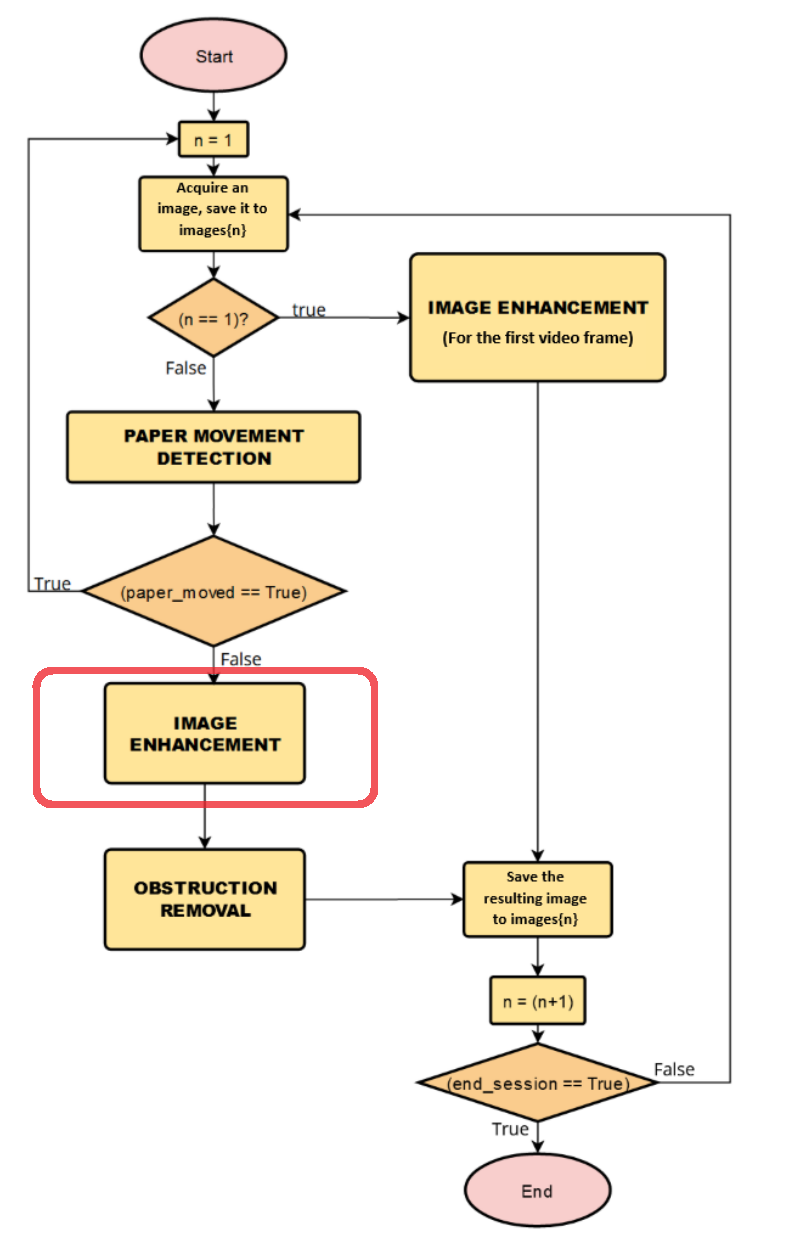

### Proposed output of the "IMAGE ENHANCEMENT" step:

The output Image should match these characteristics:

- The image should be truncated to show at maximum the enhanced white paper,

- The penstrokes on the image should be enhanced, with an increased saturation,

- The first frame will undergo its unique enhancement process so as to be transformed into a white frame and be a good reference to the next frames.

### METHODOLOGY ILLUSTRATION

In this section, we are going to illustrate the algorithm of image enhancement.The flow chart below shows basic information on the algorithm used in this presentation for the process of image enhancement. Note that the indicated numbers are the number of processes (steps) that are going to be explained.

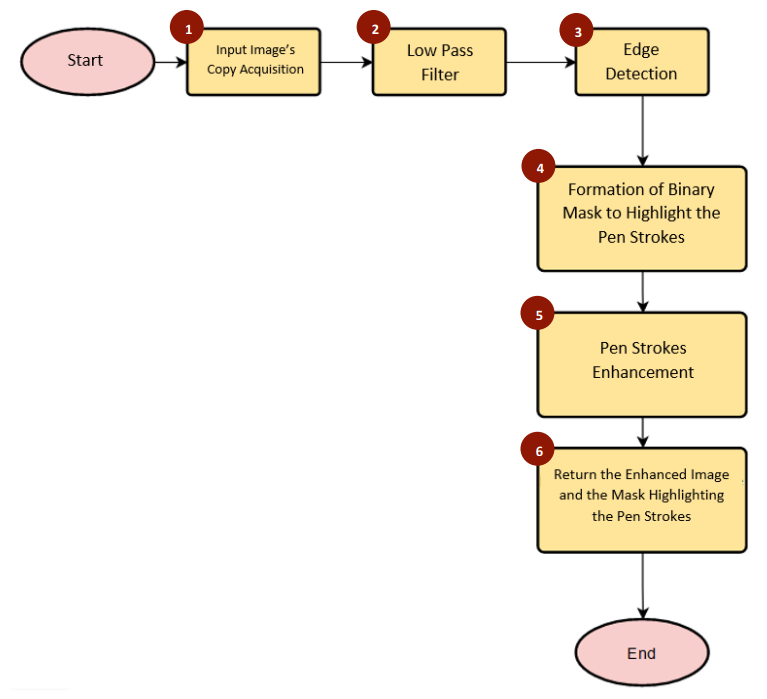

global enhancement_multiplier; 
enhancement_multiplier=2.75;
global LP_filter_PS N_smoothing Erosion_se N_erosion Dilution_se N_dilution

#### STEP 1: IMAGE ACQUISITION

At this step, the program will acquire a copy of the input image and trim it so as to get at maximum the part that shows the white paper.

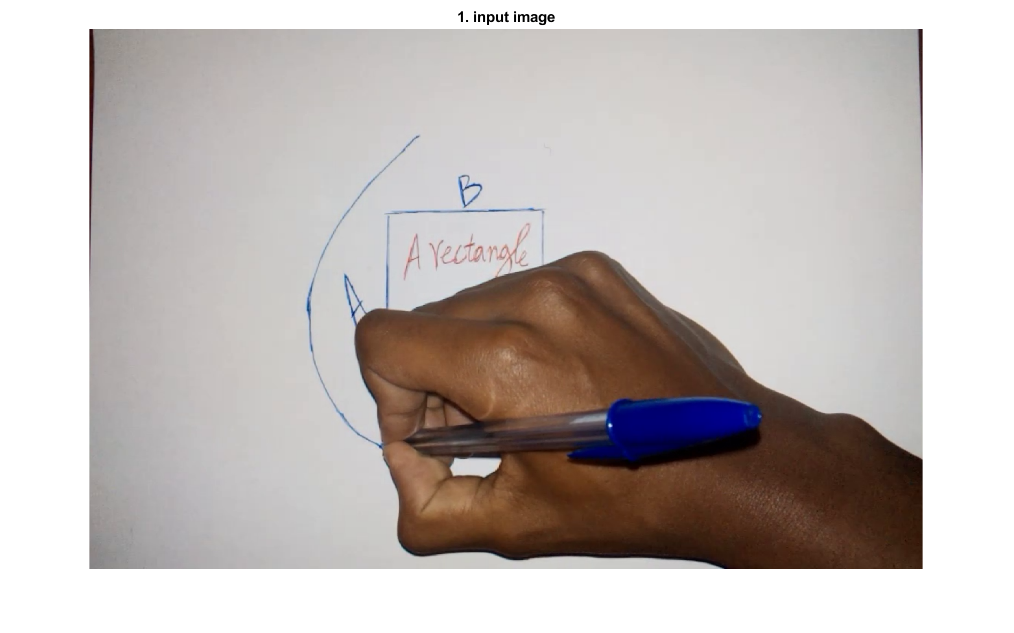


inputIm=imread("theImageWithHand.png");
[inputIm rowCr1 rowCr2 colCr1 colCr2]=whitePaperTrimmer(inputIm,0.5);
subplot(1,1,1)
imshow(inputIm)
title('1. input image')


[inputIm rowCr1 rowCr2 colCr1 colCr2]=whitePaperTrimmer(inputIm,0.1);

total_numberOfRows=rowCr2 - rowCr1 + 1;
total_numberOfColumns = colCr2 - colCr1 + 1;
theRowPeriod = ceil((0.3/100) * total_numberOfRows);
theColPeriod = ceil((0.3/100) * total_numberOfColumns);
LP_filter_PS = (1/(theColPeriod*theRowPeriod)) * ones(theRowPeriod,theColPeriod);
N_smoothing = 1;
theRowPeriod = ceil((0.035/100) * total_numberOfRows);
theColPeriod = ceil((0.035/100) * total_numberOfColumns);
Erosion_se = ones(theRowPeriod,theColPeriod);
Dilution_se = ones(theRowPeriod,theColPeriod);
N_erosion = 1;
N_dilution = 1;


#### STEP 2: LOW PASS FILTERING

This process will use an averaging filter (a low pass filter) to filter out noises in the image after converting it to grayscale. As it was stated in **[R. C. Gonzalez and R. E. Woods, *****Digital Image Processing*****, 3rd ed. Upper Saddle River, New Jersey: Pearson Prentice Hall, 2008.** **]** **[p.152]**, A major use of averaging filters is in the reduction of “irrelevant” detail in an image. By “irrelevant” we mean pixel regions that are small with respect to the size of the filter mask. Therefore, noting that the size of the filter matters, this process uses a filter whose height and width are 0.3% of the height and width of the input image (which means that the area of the filter is 0.09% of the area of the input image). That factor of 0.3% was selected after numerous try-and-see image enhancement experimentations.

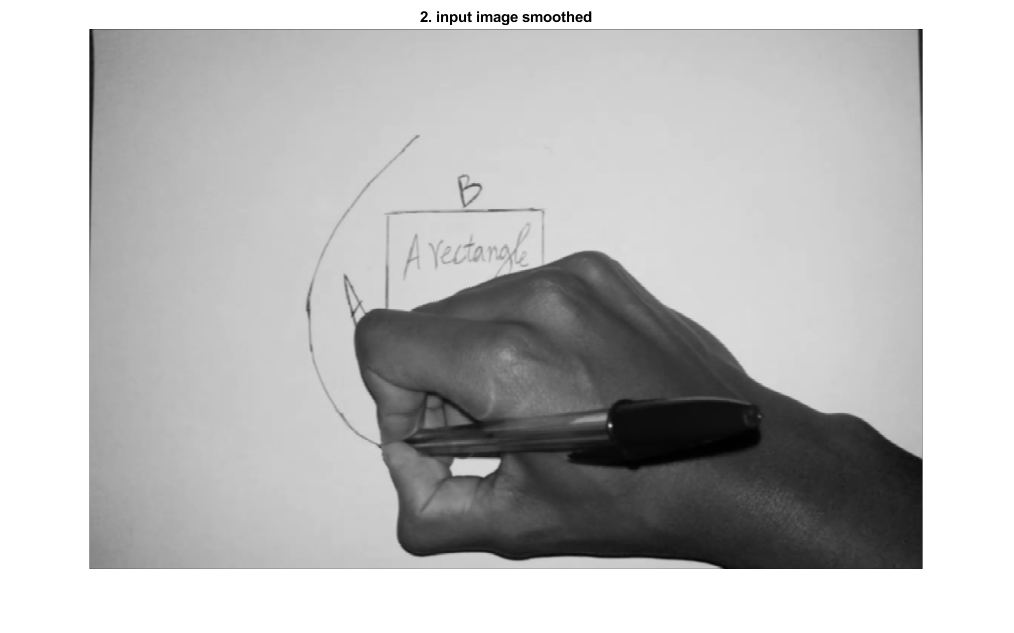

inputIm_Smoothed=inputIm;
inputIm_Smoothed = imfilter(inputIm_Smoothed,LP_filter_PS);
% imshow(inputIm_Smoothed);

inputIm_Smoothed_Gray=rgb2gray(inputIm_Smoothed);
imshow(inputIm_Smoothed_Gray)
title('2. input image smoothed')

#### STEP 3: EDGE DETECTION

This step will use a 3x3 Laplacian filter to detect edges in the image, then threshold the output so as to highlight areas where the ink has traced. Since the penstrokes can have any direction, we need an edge dectector that is isotropic. As it is stated in **[R. C. Gonzalez and R. E. Woods, *****Digital Image Processing*****, 3rd ed. Upper Saddle River, New Jersey: Pearson Prentice Hall, 2008. ] [****p. 160 and p.699****] **The Laplacian detector is isotropic, so its response is independent of direction (with respect to the four directions of the Laplacian mask: vertical, horizontal, and two diagonals).

Laplacian_Filter=[1 1 1; 1 -8 1; 1 1 1] 

Laplacian_Filter =      1     1     1
     1    -8     1
     1     1     1


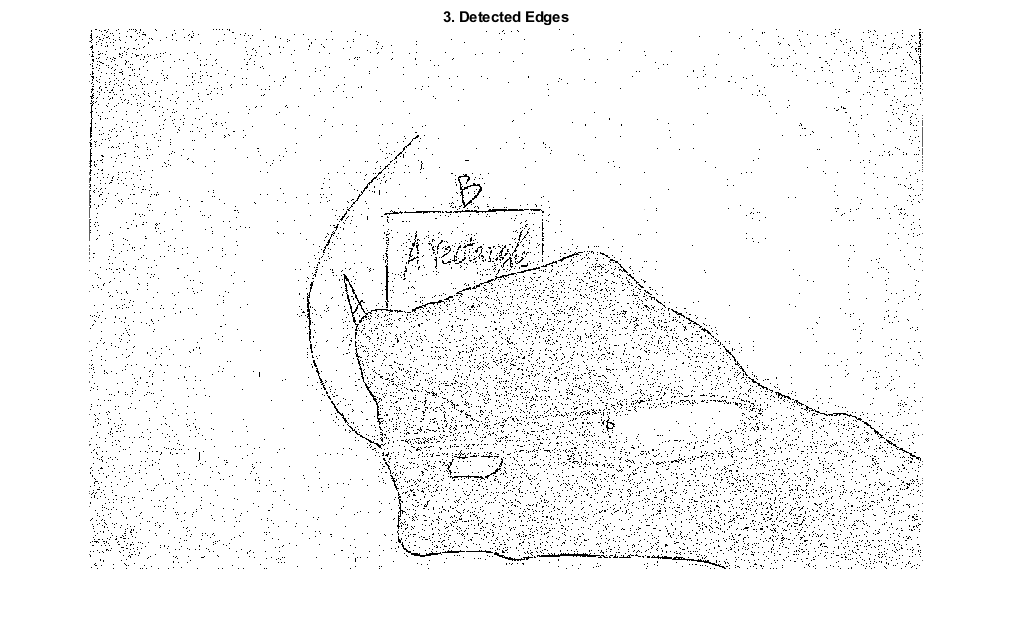

F=[1 1 1; 1 -8 1; 1 1 1] ;
inputIm_Edges=imfilter(inputIm_Smoothed_Gray,F);
inputIm_Edges = histeq(inputIm_Edges);
inputIm_MaskForPenStrokes = (inputIm_Edges < 250);
imshow(inputIm_MaskForPenStrokes)
title('3. Detected Edges')

#### STEP 4: FORMATION OF BINARY MASK TO HIGHLIGHT PENSTROKES

This step will erode the binary image, so as to enhance the highlights of penstrokes. It will also do a dilution so as to remove remaining noises. The morphological operation of erosion followed by dilation is known as "Opening Operation". As it is proved in **[R. C. Gonzalez and R. E. Woods, *****Digital Image Processing*****, 3rd ed. Upper Saddle River, New Jersey: Pearson Prentice Hall, 2008.** **] ****[632]**, the used structuring element's size matters. Therefore, this process uses a structuring element whose height and width are 0.1% of the height and width of the input image (which means that the area of the filter is 0.01% of the area of the input image). That factor of 0.1% was selected after numerous try-and-see image enhancement experimentations.

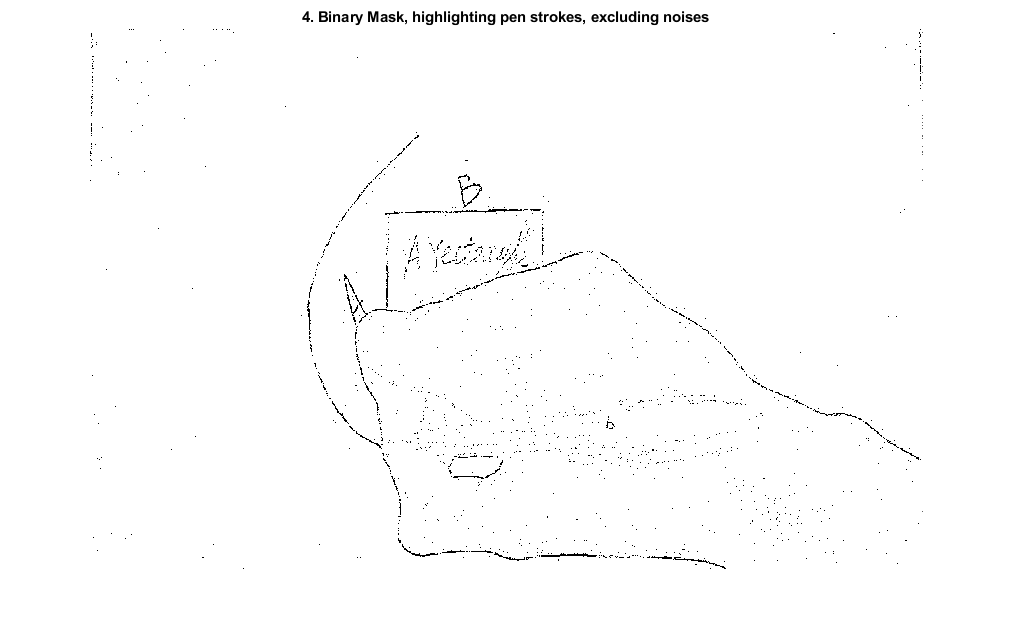

% pattern = Erosion_se;
% % pattern = ones(3);
% for t=1:1:N_erosion
%     inputIm_MaskForPenStrokes=imerode(inputIm_MaskForPenStrokes,pattern);
% end
pattern = Dilution_se;
% pattern = ones(1,2);
for t=1:1:N_dilution
    inputIm_MaskForPenStrokes=imdilate(inputIm_MaskForPenStrokes,pattern);
end

imshow(inputIm_MaskForPenStrokes)
title('4. Binary Mask, highlighting pen strokes, excluding noises')

#### STEP 5: PENSTROKES ENHANCEMENT

This process will do an element-wise multiplication between the input image and the created mask (complemented), so as to highlight the pen strokes. To increase the saturation of the penstrokes, the resulting image was converted to the HSI (Hue, Saturation and Intensity) model, and the saturation dimension was multiplied by a relatively large number (10 for our case). After the enhancement, the image was re-converted to RGB for the next steps.

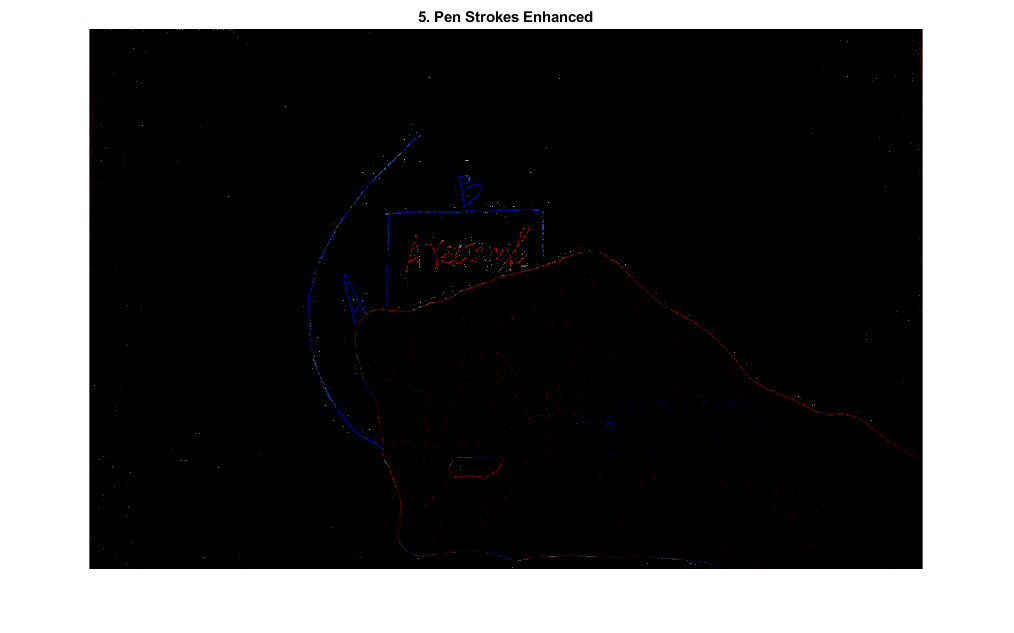


inputIm_MaskForPenStrokes = uint8(inputIm_MaskForPenStrokes);
my_white_blank = 255*ones(size(inputIm));
inputIm_WhiteArea= inputIm_MaskForPenStrokes.*uint8(my_white_blank) ;%* enhancement_multiplier;
% inimWHITE= inputMask * 255 ;

inputIm = uint8(~inputIm_MaskForPenStrokes) .* inputIm;
inputIm_Penstrokes_Unsaturated = inputIm;
inputIMAGE_HSV=rgb2hsv(inputIm);
inputIMAGE_HSV(:,:,2)=inputIMAGE_HSV(:,:,2)*10;
inputIm=hsv2rgb(inputIMAGE_HSV);

imshow(uint8(inputIm*255));
title('5. Pen Strokes Enhanced')

#### STEP 6: RETURNING THE ENHANCED IMAGE AND THE BINARY MASK

This process will set the remaining part (the part which does not represent penstrokes) to higher intensity levels, by multiplying it with a constant. The part is then added to the part that represents penstrokes. After that, it will return the enhanced image and a binary mask to be later used in obstruction removal process, so as to protect pen strokes from being considered as obstruction (see the next topic: Obstruction Removal)

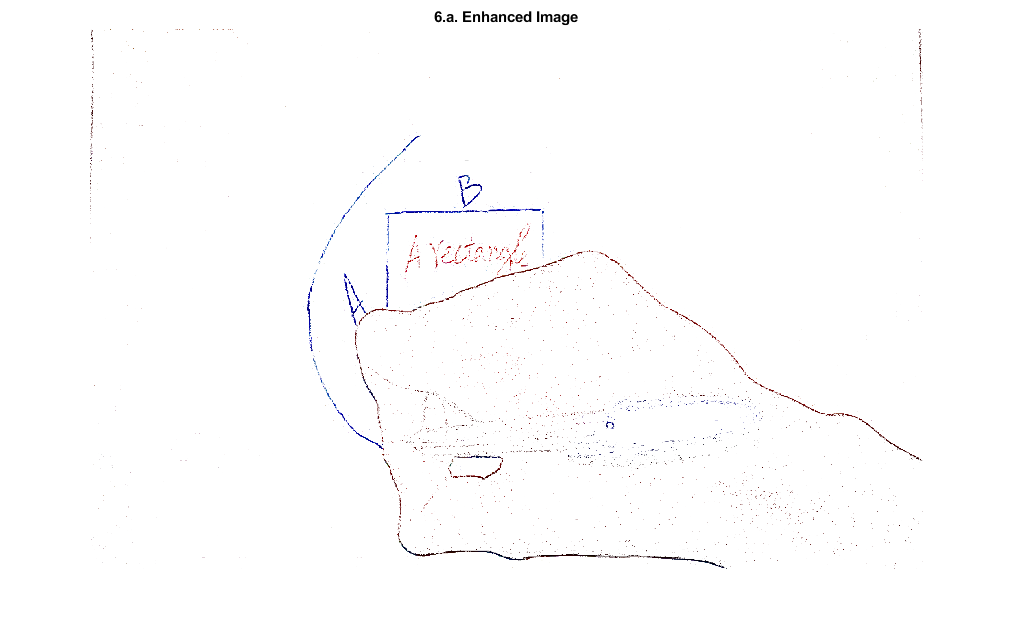

outputIMAGE= uint8(inputIm_WhiteArea) + uint8(inputIm*255);
outputImage3 = outputIMAGE;
imshow(outputIMAGE)
title('6.a. Enhanced Image')

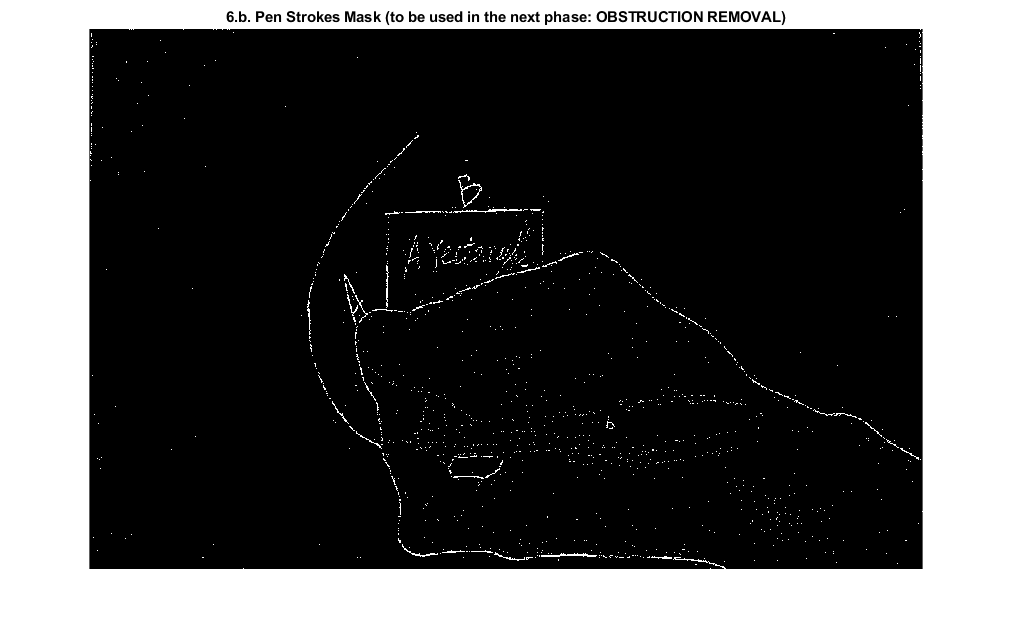


global mypenstroke_mask
mypenstroke_mask = ~inputIm_MaskForPenStrokes;
imshow(mypenstroke_mask)
title('6.b. Pen Strokes Mask (to be used in the next phase: OBSTRUCTION REMOVAL)')

### ALGORITHM IMPROVEMENT

By experimentation, It was found that step 5 (Penstrokes Enhancement) took too much time for execution, due to the convertion from RGB to HSI and vice-versa. The process of RGB-HSI conversion, requires complex calculations such as trigonometric and inverse trigonometric functions. These calculations result in low algorithmic efficiency (time efficiency). For this reason, various approaches to improving the RGB to HSI conversion has been proposed, as it can be found in **[S. Zhi, Y. Cui, J. Deng, and W. Du, “An FPGA-based simple RGB-hsi space conversion algorithm for hardware image processing,” *****IEEE Access*****, vol. 8, pp. 173838–173853, Oct. 2020.** **]**. Given that our case needed to increase only the saturation parameter, we developed our own approach so as to tackle with the challenge of time efficiency, as a real-time constraint. The new approach proposed was to divide by three the sum of the Red, Green and Blue components' intensities, so as to get the average intensity for each pixel. Next, the original intensities of the Red, Green and Blue components were compared to the resulting average so as to determine which intensities are major in each pixel. The intensities that were found to be greater than the average were set to the maximum intensity (which is 255), while the intensities that were found to be less than the average were set to the lowest intensity (which is 0).

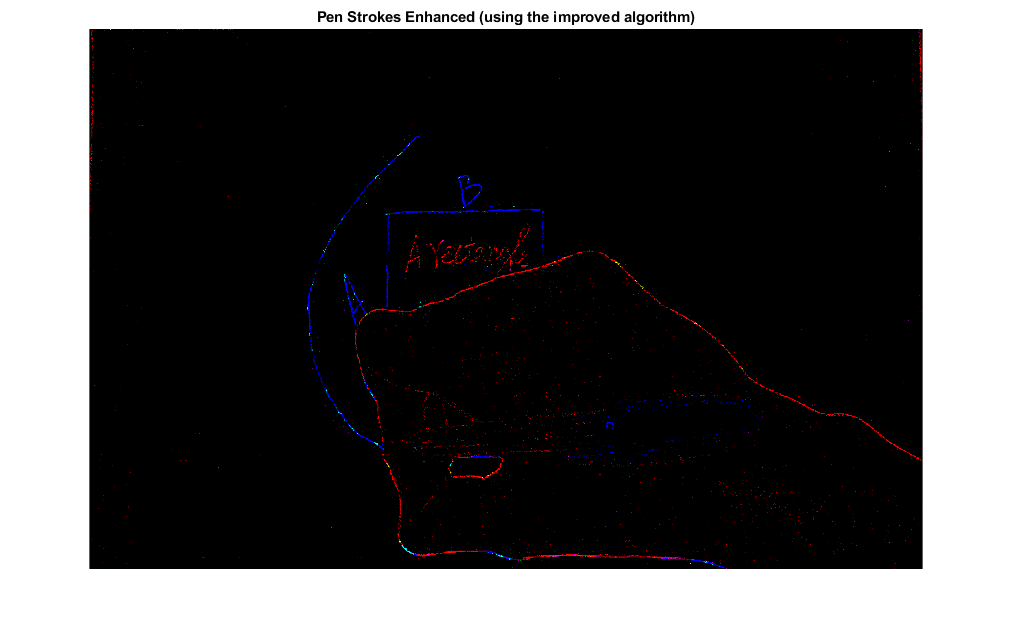

inputIm_average = inputIm_Penstrokes_Unsaturated(:,:,1)/3+inputIm_Penstrokes_Unsaturated(:,:,2)/3+inputIm_Penstrokes_Unsaturated(:,:,3)/3;
penstrokes_Saturated = inputIm_Penstrokes_Unsaturated;
penstrokes_Saturated(:,:,1) = 255*uint8(inputIm_Penstrokes_Unsaturated(:,:,1) > inputIm_average);
penstrokes_Saturated(:,:,2) = 255*uint8(inputIm_Penstrokes_Unsaturated(:,:,2) > inputIm_average);
penstrokes_Saturated(:,:,3) = 255*uint8(inputIm_Penstrokes_Unsaturated(:,:,3) > inputIm_average);
imshow(penstrokes_Saturated)
title('Pen Strokes Enhanced (using the improved algorithm)')

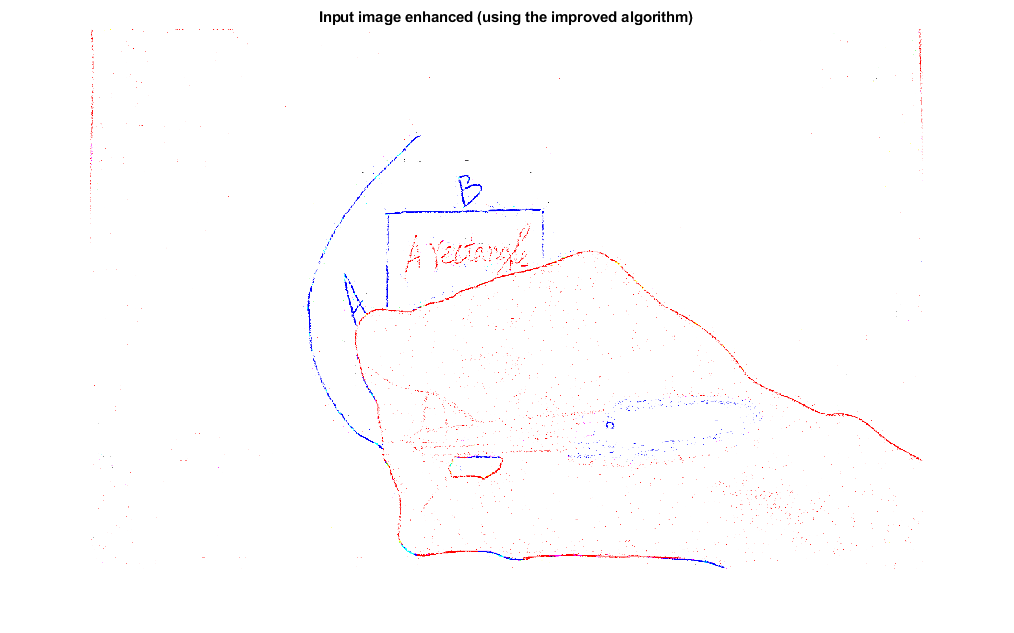

outputIm= (inputIm_WhiteArea) + penstrokes_Saturated;
imshow(outputIm);
title('Input image enhanced (using the improved algorithm)')

### COMPARISION OF TIME USAGE BETWEEN THE HSI APPROACH AND THE IMPROVED APPROACH.

In this section, we are going to compare the time usage of the two approaches: the HSI approach against the improved approach. We will generate different random images of 1 megapixels to 5 megapixels and graph the time it will take for the computer to execute each dataset using each of the two approaches. For each approach, the computer will execute the step number 3, assuming that the given image represents the RGB image to be processed.

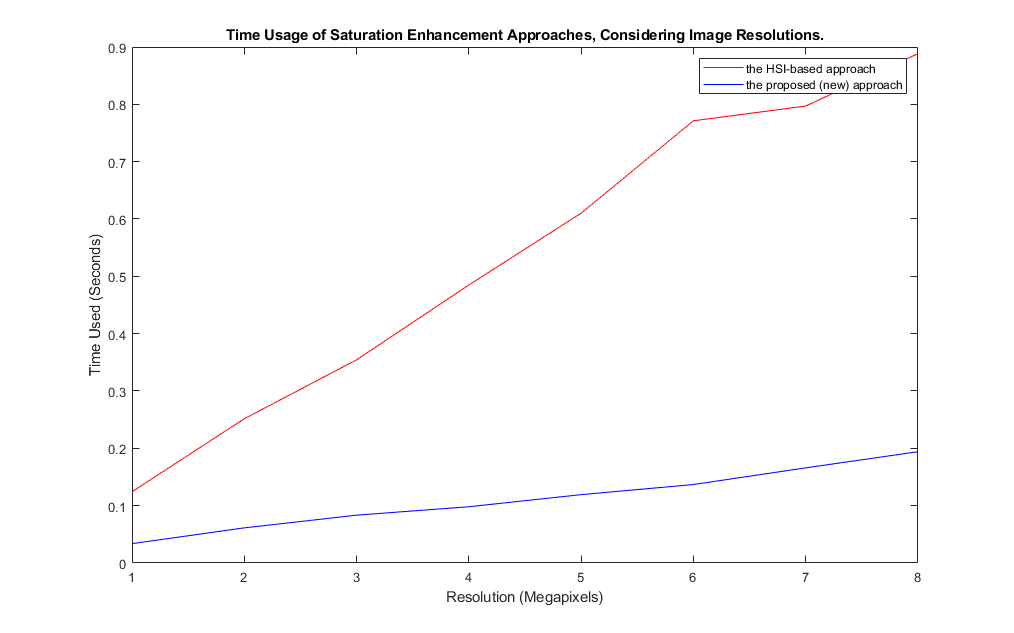

cstant = 10000;
i100_pixels=uint8(255*rand(10*cstant,10,3));
i200_pixels=uint8(255*rand(20*cstant,10,3));
i300_pixels=uint8(255*rand(30*cstant,10,3));
i400_pixels=uint8(255*rand(40*cstant,10,3));
i500_pixels=uint8(255*rand(50*cstant,10,3));
i600_pixels=uint8(255*rand(60*cstant,10,3));
i700_pixels=uint8(255*rand(70*cstant,10,3));
i800_pixels=uint8(255*rand(80*cstant,10,3));

tic;
hsi_Approach(i100_pixels);
t_hsi(1)=toc;
tic;
hsi_Approach(i200_pixels);
t_hsi(2)=toc;
tic;
hsi_Approach(i300_pixels);
t_hsi(3)=toc;
tic;
hsi_Approach(i400_pixels);
t_hsi(4)=toc;
tic;
hsi_Approach(i500_pixels);
t_hsi(5)=toc;
tic;
hsi_Approach(i600_pixels);
t_hsi(6)=toc;
tic;
hsi_Approach(i700_pixels);
t_hsi(7)=toc;
tic;
hsi_Approach(i800_pixels);
t_hsi(8)=toc;

tic;
new_Approach(i100_pixels);
t_new(1)=toc;
tic;
new_Approach(i200_pixels);
t_new(2)=toc;
tic;
new_Approach(i300_pixels);
t_new(3)=toc;
tic;
new_Approach(i400_pixels);
t_new(4)=toc;
tic;
new_Approach(i500_pixels);
t_new(5)=toc;
tic;
new_Approach(i600_pixels);
t_new(6)=toc;
tic;
new_Approach(i700_pixels);
t_new(7)=toc;
tic;
new_Approach(i800_pixels);
t_new(8)=toc;

plot(1:1:8,t_hsi,'r',1:1:8,t_new,'b')
title("Time Usage of Saturation Enhancement Approaches, Considering Image Resolutions.")
xlabel("Resolution (Megapixels)")
ylabel("Time Used (Seconds)")
legend({'the HSI-based approach','the proposed (new) approach'})

From the figure above, it can be seen that the new (proposed) approach uses less time than the HSI approach. In order to ensure time effiency, the proposed approach was chosen to be implemented.

## III. Obstruction Removal.

After the Image Enhancement process, the system will need to compensate for the obstructed part of the input image.The following flowchart indicates where the Obstruction Removal process belongs to in the main algorithm.

### 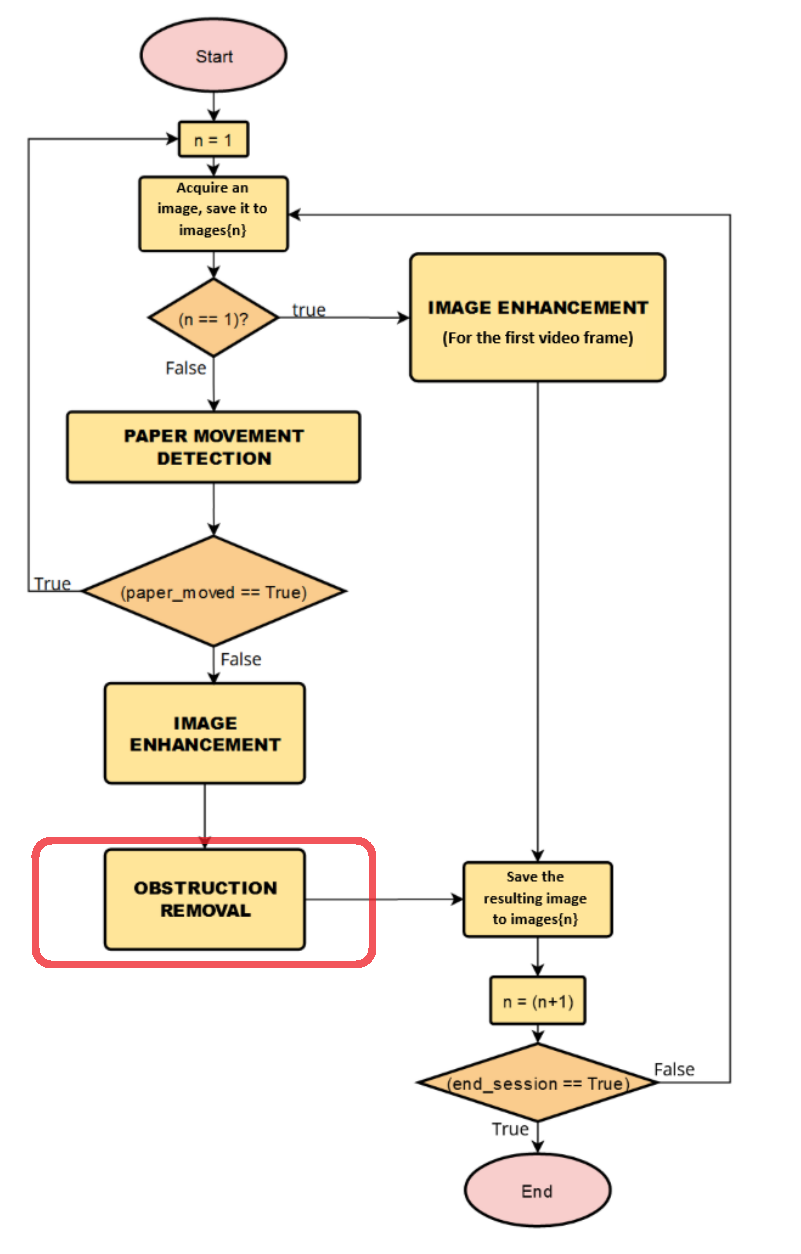

### METHODOLOGY ILLUSTRATION

In this section, we are going to illustrate the algorithm of obstruction removal.The flowchart below shows basic information on the Obstruction removal algorithm that we are going to explain here below. Note that the indicated numbers are the number of processes (steps) that are going to be explained.

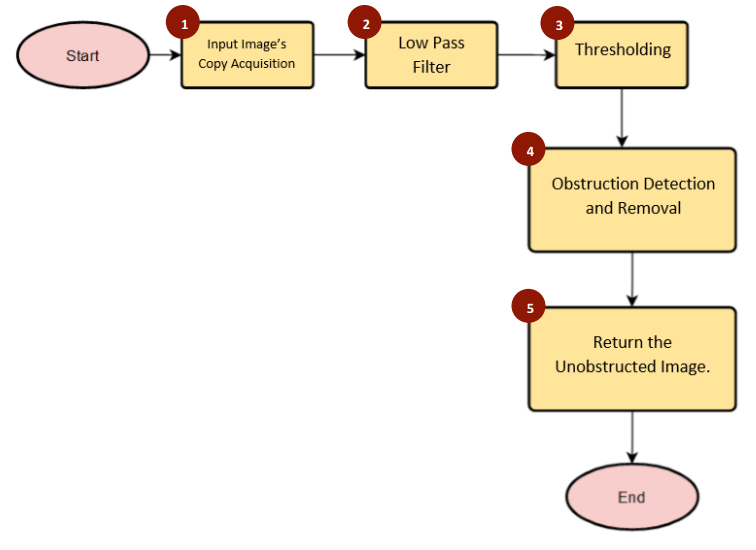

#### STEP 1: IMAGE ACQUISITION

At this step, the program will read the input image and trim it so as to get at maximum the part that shows the white paper. 

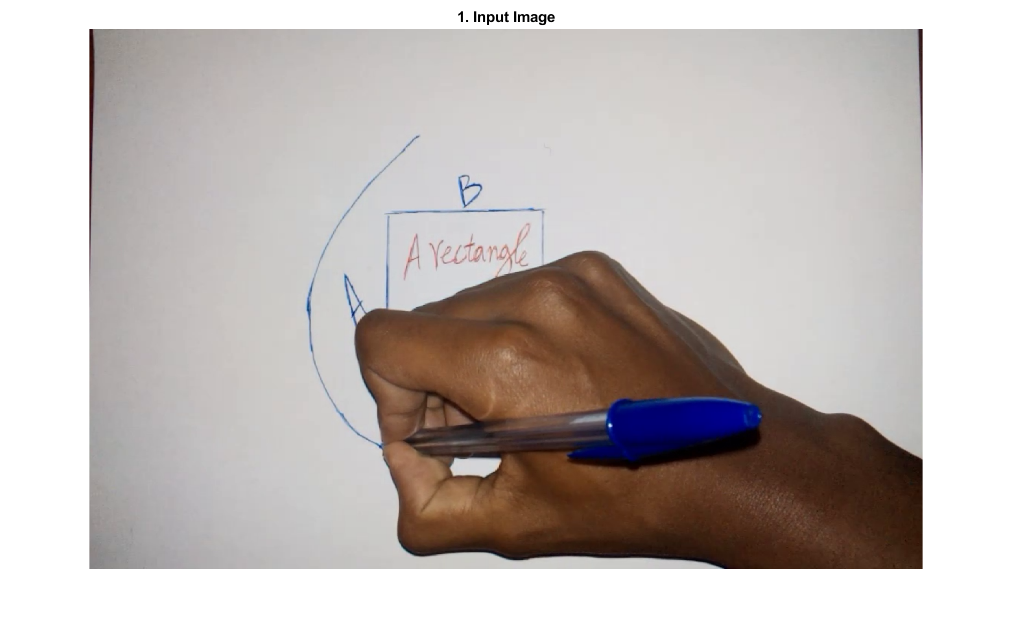

inputIm=imread("theImageWithHand.png");
% inputIm=imread("theImage.png");
[inputIm rowCr1 rowCr2 colCr1 colCr2]=whitePaperTrimmer(inputIm,0.5);
imshow(inputIm);
title("1. Input Image")

clear Mask_RGB


#### STEP 2: LOW PASS FILTERING

This process will use a low pass filter to filter out any object that appears in the image, except only the obstruction (the hand). As it was stated in **[R. C. Gonzalez and R. E. Woods, *****Digital Image Processing*****, 3rd ed. Upper Saddle River, New Jersey: Pearson Prentice Hall, 2008.** **]** **[p.152]**, A major use of averaging filters is in the reduction of “irrelevant” detail in an image. By “irrelevant” we mean pixel regions that are small with respect to the size of the filter mask. Therefore, noting that the size of the filter matters, this process uses a filter whose height and width are 1.5% of the height and width of the input image (which means that the area of the filter is 2.25% of the area of the input image). That factor of 1.5% was selected after numerous try-and-see image enhancement experimentations.

The process will use the binary mask from the image enhancement process so as to highlight penstrokes, and make sure that they do not contribute to the obstruction pixels by setting them to the highest intensity value, 255 (This will also prevent the effect of inequal illumination from obstructing the penstrokes). Then the resulting image will be filtered by smoothing.

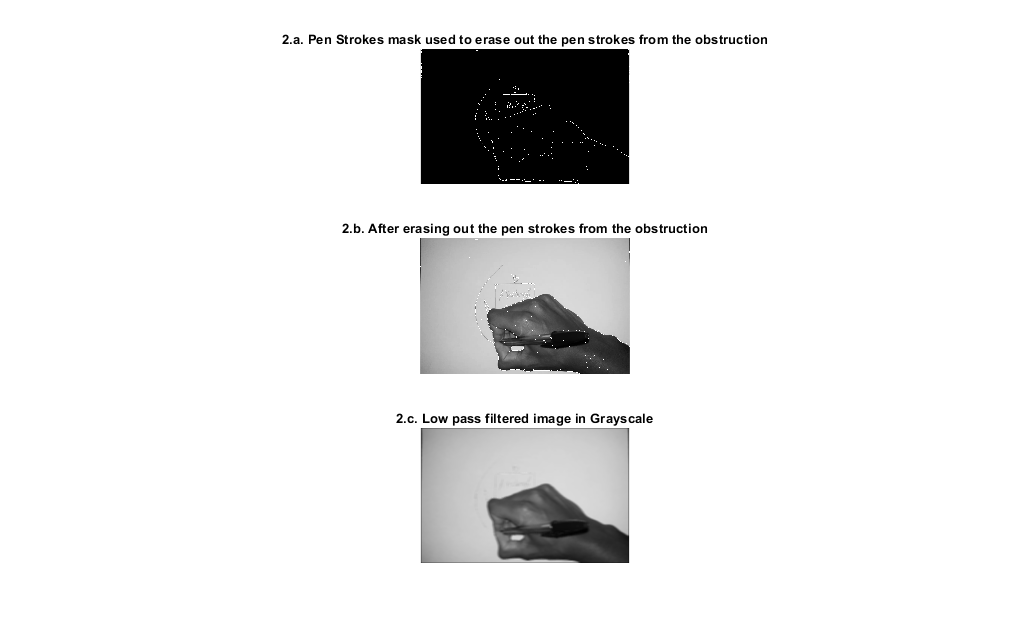

total_numberOfRows=rowCr2 - rowCr1 + 1;
total_numberOfColumns = colCr2 - colCr1 + 1;
theRowPeriod = ceil((1.5/100) * total_numberOfRows);
theColPeriod = ceil((1.5/100) * total_numberOfColumns);
LP_filter_Hand = (1/(theColPeriod*theRowPeriod)) * ones(theRowPeriod,theColPeriod);

global mypenstroke_mask
subplot(3,1,1)
imshow(mypenstroke_mask);
title("2.a. Pen Strokes mask used to erase out the pen strokes from the obstruction")
inputIm_Smoothed=rgb2gray(inputIm);
inputIm_Smoothed(mypenstroke_mask)= uint8(255);
subplot(3,1,2)
imshow(inputIm_Smoothed);
title("2.b. After erasing out the pen strokes from the obstruction")
inputIm_Smoothed = imfilter(inputIm_Smoothed,LP_filter_Hand);
subplot(3,1,3)
imshow(inputIm_Smoothed);
title("2.c. Low pass filtered image in Grayscale")

#### STEP 3: THRESHOLDING

This process will threshold the smoothed outpout image from step 2. As various thresholding models rely on contrast enhancement (**[P. Kandhway and A. K. Bhandari, “An optimal adaptive thresholding based sub-histogram equalization for brightness preserving image contrast enhancement,” *****Multidimensional Systems and Signal Processing*****, vol. 30, no. 4, pp. 1859–1894, Feb. 2019. ]** and **[****S. N and V. S, “Image segmentation by using thresholding techniques for medical images,” *****Computer Science & Engineering: An International Journal*****, vol. 6, no. 1, pp. 1–13, Feb. 2016. ****]**), the image equalization will enhance the contrast significantly, so as to prepare the image for the thresholding. By thresholding the image, the process' results will make sure that the obstruction will be represented by 0 intensity pixels.

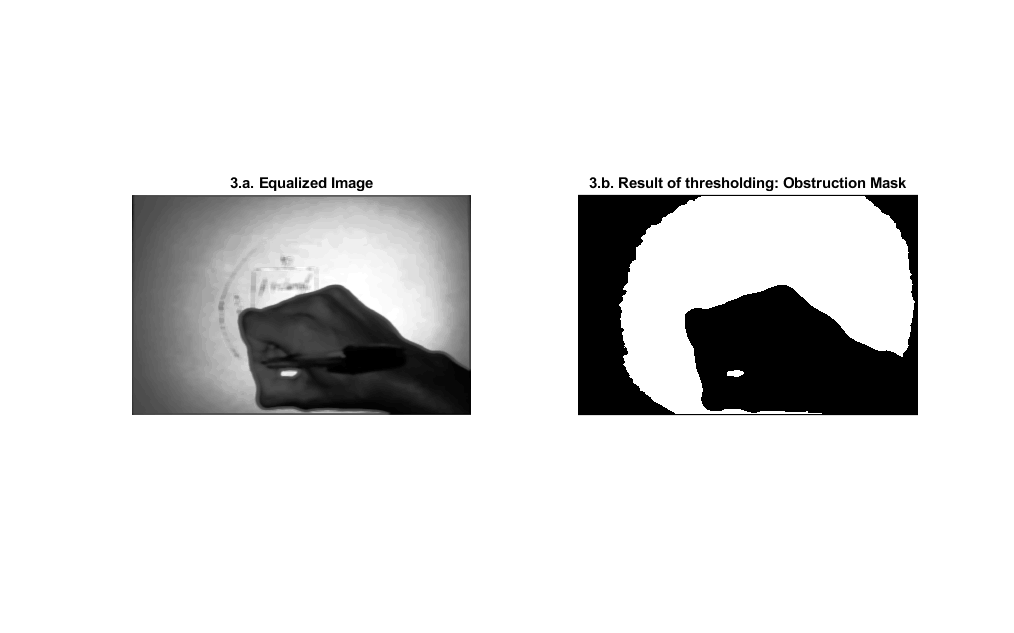

inputIm_Smoothed_eq=histeq(inputIm_Smoothed);
subplot(1,2,1)
imshow(inputIm_Smoothed_eq)

title("3.a. Equalized Image")
inputIm_Smoothed_eq_gray = (inputIm_Smoothed_eq);
inputIm_MaskOfObstruction_Binary = imbinarize(inputIm_Smoothed_eq_gray,0.5);
subplot(1,2,2)
imshow(inputIm_MaskOfObstruction_Binary)
title("3.b. Result of thresholding: Obstruction Mask")

#### STEP 4: OBSTRUCTION REMOVAL

This process will replicate the created obstruction mask into three dimensions so as to multiply (element-wise multiplication) with the input image, thus remove the obstruction by setting the obstruction to zero intensity. The zero intensities will be compansated by previous frame through addition.

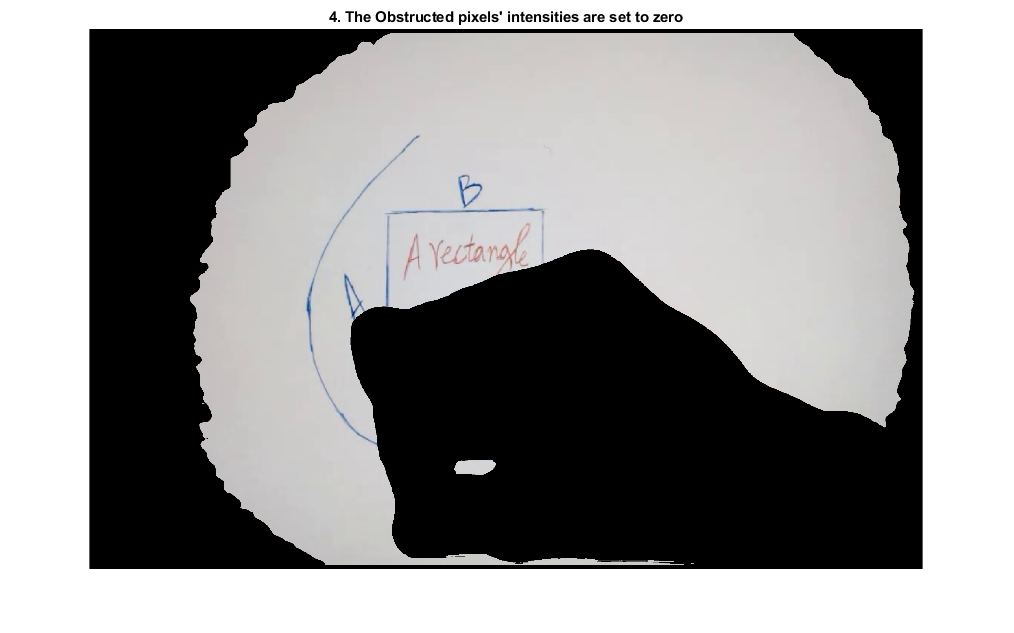

inputIm_MaskOfObstruction_Binary=uint8(inputIm_MaskOfObstruction_Binary);
Mask_RGB(:,:,1)=inputIm_MaskOfObstruction_Binary;
Mask_RGB(:,:,2)=inputIm_MaskOfObstruction_Binary;
Mask_RGB(:,:,3)=inputIm_MaskOfObstruction_Binary;

% inputIm = imread("theImageWithHandEnhanced.png");
outputIm=inputIm.*(Mask_RGB);
subplot(1,1,1)
imshow(outputIm)
title("4. The Obstructed pixels' intensities are set to zero")

It can be seen that even though the illumination correction is a challenge, all the penstrokes were protected from obstruction. This was due to that, at step 2, we used the penstrokes mask to protect the penstrokes.

### STEP 5: RETURN THE OUTPUT IMAGE

This step will return the output image to the main program. As shown in the figure below, The output image (above) will be added to the output image processed from the previous frame, so as to get a final obstruction free image. (The figure below assumes that both the previous image / frame and current image / frame are enhanced).